## Task 0 :Uploading the audio file and getting its data

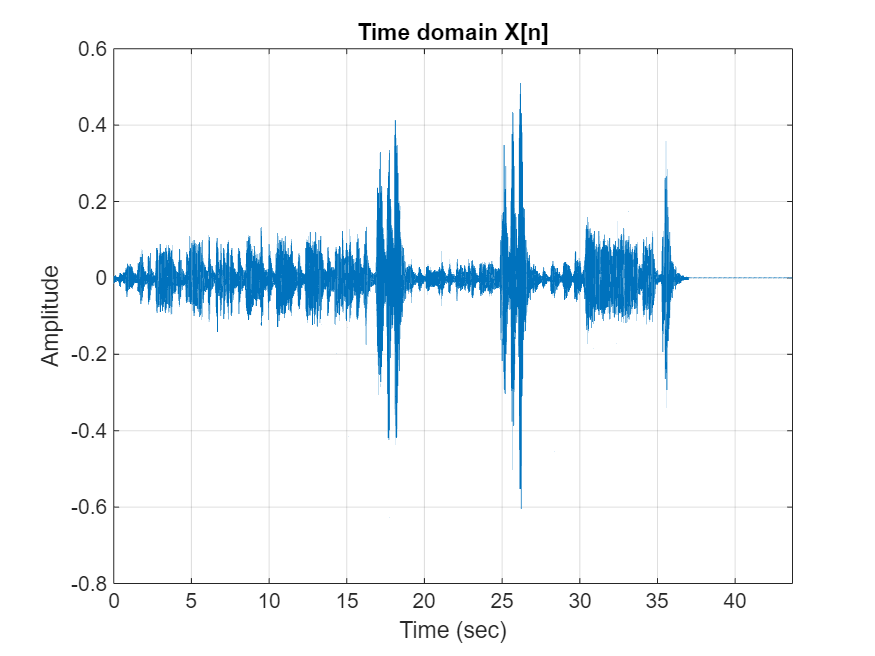

[xn,fs] = audioread('sample_audio_file.wav');
% convert from stero to mono 
xn = mean(xn,2);
N_xn = length(xn);
% axis of drawing 
t = linspace(0, N_xn/fs ,N_xn);
% divided by fs or N ? 
xf = abs(fftshift(fft(xn))) / fs;
%xf_N = abs(fftshift(fft(xn))) / N_xn;
%xf = xf(1:N/2);
f = linspace(-fs/2, fs/2 ,N_xn);

figure
plot(t,xn)
grid on
title('Time domain X[n]')
xlabel('Time (sec)')
ylabel('Amplitude')
xlim([0, N_xn/fs])

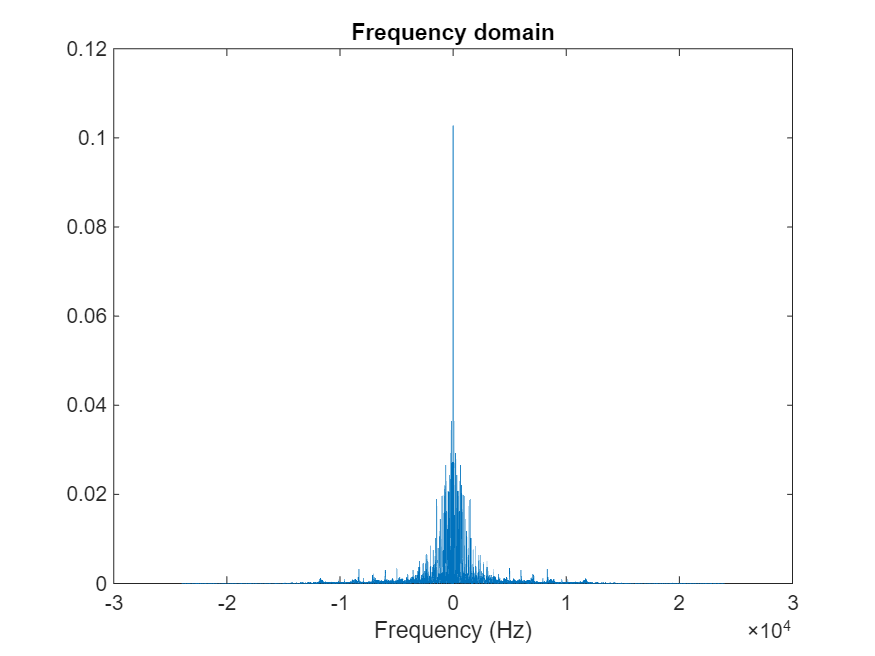

figure
plot(f,xf)
%plot(f,xf_N)
title('Frequency domain')
xlabel('Frequency (Hz)')

## Task 0 : Calcualation of the total energy in Time

Et = sum(xn.^2)/fs

Et = 0.0421

Ef = (sum((abs(xf).^2)*fs))/N_xn 

Ef = 0.0421